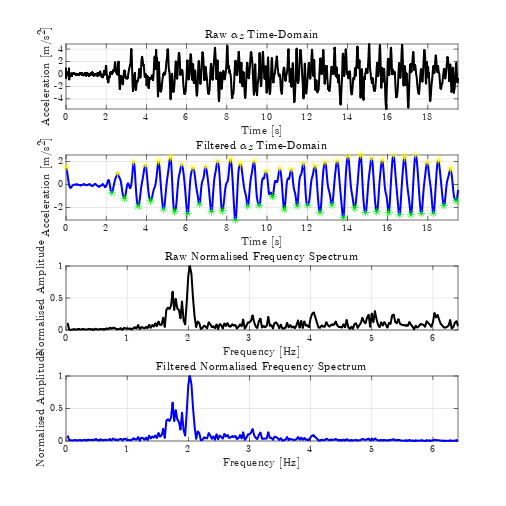

clear
clc
clf
set(0,'defaulttextinterpreter','latex');
walking_data = dlmread('walkingdata_az_raw_filt_order_4_Test_1.txt', '\t'); %#ok<DLMRD>
raw_data = walking_data(:,1);
filt_data = walking_data(:,2);
numSamples = length(raw_data);
Ts = 0.0078;  % Sampling period
fs = 1/Ts; % Sampling frequency

% Time parameters
time_elapsed = Ts * numSamples;
t = (0:Ts:Ts * numSamples - Ts);

% Compute the Fourier Transform - raw signal
frequencies = (fs/numSamples*(1:numSamples / 2));
ft_walk = fft(raw_data);
max_amplitude_walk = max(abs(ft_walk));
norm_amplitude = abs(ft_walk(1:numSamples / 2)) / max_amplitude_walk;

% Compute and plot the Fourier Transform - filtered signal
ft_filtered = fft(filt_data);
max_amplitude_filtered = max(abs(ft_filtered));
norm_amplitude_filtered = abs(ft_filtered(1:numSamples / 2)) / max_amplitude_filtered;

% Find peaks in filtered data
[maxtab, mintab] = peakdet(filt_data, 1.5, t);

% Plot colours
Gray = [.5 .5 .5];
RGB_Violet = [0.4940 0.1840 0.5560];
RGB_Maroon = [0.6350 0.0780 0.1840];
RGB_Yellow = [0.9290 0.6940 0.1250];
RGB_Orange = [0.8500 0.3250 0.0980];
RGB_Forest = [0.4660 0.6740 0.1880];
RGB_Blue = [0 0.4470 0.7410];

% Create the plot
figure(1);
subplot(4, 1, 1);
plot(t, raw_data, 'LineWidth', 1.5, 'Color', 'k');
title('Raw ${\alpha_z}$ Time-Domain');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid on;
xlim([0 time_elapsed/2]);

subplot(4, 1, 2);
plot(t, filt_data, 'LineWidth', 1.5, 'Color', 'b');
title('Filtered ${\alpha_z}$ Time-Domain', 'Interpreter', 'latex');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid on;
xlim([0 time_elapsed/2]);
hold on; 
plot(mintab(:,1), mintab(:,2), 'g*');
plot(maxtab(:,1), maxtab(:,2), 'y*');
hold off;

subplot(4, 1, 3);
plot(frequencies, norm_amplitude, 'LineWidth', 1.5, 'Color', 'k');
title('Raw Normalised Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Normalised Amplitude');
grid on;
xlim([0 max(frequencies)/10]);

subplot(4, 1, 4);
plot(frequencies, norm_amplitude_filtered, 'LineWidth', 1.5, 'Color', 'b');
title('Filtered Normalised Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Normalised Amplitude');
grid on;
xlim([0 max(frequencies)/10]);

% Adjust the size of the entire figure
set(gcf, 'Position', [100, 100, 800, 800]);

fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 16]; % This will stretch the plot across an 11x8.5 inch page
fig.PaperSize = [20 16];

% Use the following command to save the figure in MATLAB
print(fig, 'ELEC0036_Arduino_Butter_FFT','-depsc','-r600');

function [maxtab, mintab]=peakdet(v, delta, x)
%PEAKDET Detect peaks in a vector
%        [MAXTAB, MINTAB] = PEAKDET(V, DELTA) finds the local
%        maxima and minima ("peaks") in the vector V.
%        MAXTAB and MINTAB consists of two columns. Column 1
%        contains indices in V, and column 2 the found values.
%      
%        With [MAXTAB, MINTAB] = PEAKDET(V, DELTA, X) the indices
%        in MAXTAB and MINTAB are replaced with the corresponding
%        X-values.
%
%        A point is considered a maximum peak if it has the maximal
%        value, and was preceded (to the left) by a value lower by
%        DELTA.

% Eli Billauer, 3.4.05
% This function is released to the public domain; Any use is allowed.

maxtab = [];
mintab = [];

v = v(:); % Just in case this wasn't a proper vector

if nargin < 3
  x = (1:length(v))';
else
  x = x(:);
  if length(v)~= length(x)
    error('Input vectors v and x must have same length');
  end
end

if (length(delta(:)))>1
  error('Input argument DELTA must be a scalar');
end

if delta <= 0
  error('Input argument DELTA must be positive');
end

mn = Inf; mx = -Inf;
mnpos = NaN; mxpos = NaN;

lookformax = 1;

for i=1:length(v)
  this = v(i);
  if this > mx, mx = this; mxpos = x(i); end
  if this < mn, mn = this; mnpos = x(i); end

  if lookformax
    if this < mx-delta
      maxtab = [maxtab ; mxpos mx]; %#ok<AGROW> 
      mn = this; mnpos = x(i);
      lookformax = 0;
    end
  else
    if this > mn+delta
      mintab = [mintab ; mnpos mn]; %#ok<AGROW>
      mx = this; mxpos = x(i);
      lookformax = 1;
    end
  end
end
end